# Retratos de fase (Phase portraits)

## Presa - Depredador

Para realizar los retratos de fase, se utilizará el modelo clásico de presa depredador de Lotka-Volterra.


$$\dot{P}(t)= \alpha P(t) - \beta P(t)D(t)\\
\dot{D}(t)= \delta P(t) D(t) - \gamma D(t)$$


**Con los siguientes parámetros y estados:**

$P(t)$: Número de presas en el tiempo

$D(t)$: Depredadores en el tiempo

$\alpha$: Tasa instantánea de aumento de presas en ausencia de depredadores

$\beta$: Tasa de cacería de número de presas por depredador

$\delta$: Tasa de aumento de depredadores por presa cazada

$\gamma$: Tasa instantánea de disminución de depredadores en ausencia de presas

**1.** Primero se debe crear el modelo de interés, en este caso será el modelo de presa depredador clásico de Lotka-Volterra 

Para esto creamos una función con los parámetros y ecuaciones incluidas en su interior (en este caso *PresaDepredador.m *en la carpeta *funciones*).

addpath("funciones")

f = @PresaDepredador; %modelo creado a partir de la funcion PresaDepredador

**Nota:** También, si no se desea crear un archivo con el sistema de ecuaciones, es posible utilizar *Handle functions* en Matlba. Con estas podemos definir funciones de manera directa en el script, la ventaja es que no es necesario abrir un archivo para cambiar el valor de los parámetros.

**2.** Posteriormente se definen los parámetros para realizar el retrato de fase

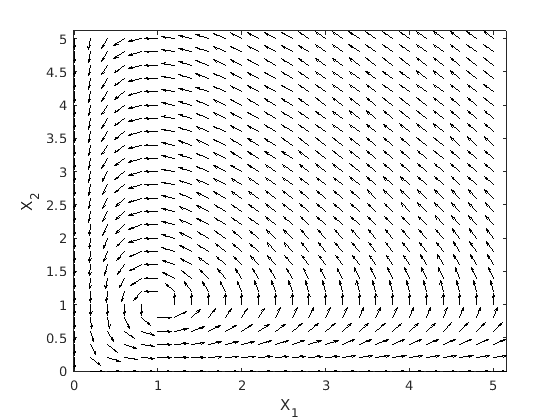

intervalX1 = 0 : 0.2 : 5; % intervalo para estado 1 (x1)
intervalX2 = 0 : 0.2 : 5; % intervalo para estado 2 (x2)

figure
vectfieldn(f, intervalX1, intervalX2)
xlabel("X_1")
ylabel("X_2")

**3. **Graficar algunas trayectorias dejando fija la condición inicial del estado x1 y variando la condición inicial del estado x2

Los circulos rojos representan las condiciones iniciales y los cuadros negros las condiciones finales

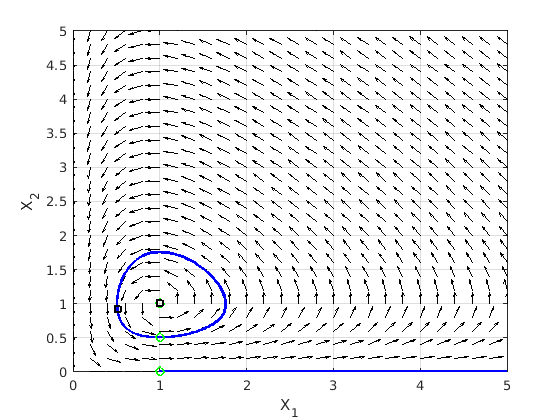

figure
vectfieldn(f, intervalX1, intervalX2)  
hold on
ydom = linspace(0, 50, 1000);
X10 = 1;            %Condicion inicial para las presas

for X20 = [0 0.5 1] %multiples condiciones iniciales para los depredadores
    
    [~, ysim] = ode45(@(t,Y) f(t,Y), ydom, [X10, X20]);
    plot(ysim(:, 1), ysim(:, 2), 'b', 'LineWidth', 2)                   %Trayectoria de estado
    plot(ysim(1, 1), ysim(1, 2),'o', 'color', 'g', 'LineWidth',2)       %Punto inicial
    plot(ysim(end, 1), ysim(end, 2),'s', 'color', 'k', 'LineWidth',2)   %Punto final
    
end

xlim([intervalX1(1) intervalX1(end)])
ylim([intervalX2(1) intervalX2(end)])
grid on
xlabel("X_1")
ylabel("X_2")

Ahora, las simulaciones de cada variable en el tiempo de acuerdo a las condiciones iniciales anteriormente descritas se presentan a continuación:

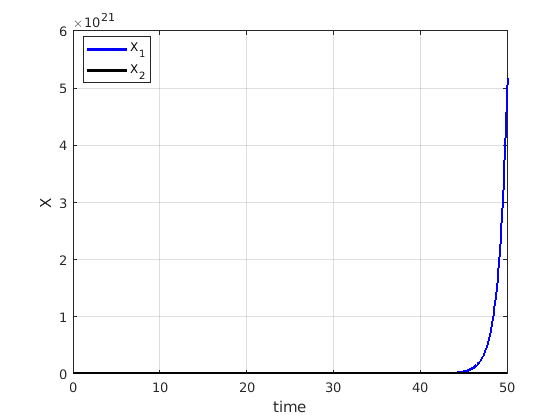

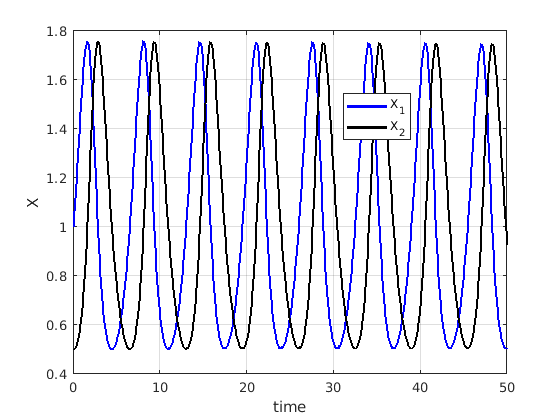

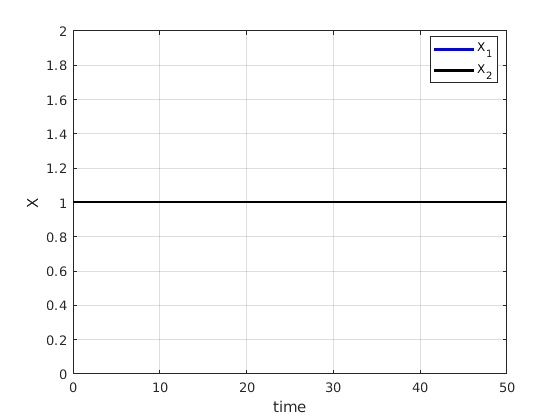

for X20 = [0 0.5 1]
    figure
    
    [tsim,ysim] = ode45(@(t,Y) f(t,Y), ydom, [X10, X20]);
    plot(tsim, ysim(:, 1), 'b', 'LineWidth', 2)
    hold on
    plot(tsim, ysim(:, 2), 'k', 'LineWidth', 2)  
    
    xlabel('time')
    ylabel('X')
    legend('X_1', 'X_2', 'Location', 'best')
    grid on
end